## ECE 586 Markov Chain Project

% Fill in all lines with "###"
% Functions after %%%%%% need to be implemented
clc
clear all
close all

**Exercise 2.1**

What is the distribution of the number of fair coin tosses before one observes 3 heads in a row? To solve this, consider a 4-state Markov chain with transition probability matrix

P = $\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0\ldotp 5 & 0 & 0\\
0\ldotp 5 & 0 & 0\ldotp 5 & 0\\
0\ldotp 5 & 0 & 0 & 0\ldotp 5\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

where 𝑋𝑡=1 if the previous toss was tails, 𝑋𝑡=2 if the last two tosses were tails then heads, 𝑋𝑡=3 if the last three tosses were tails then heads twice, and 𝑋𝑡=4 is an absorbing state that is reached when the last three tosses are heads.

- Write a computer program (e.g., in Python) to compute Pr(𝑇1,4=𝑚) for 𝑚=1,2,…,100 and use this to estimate expected number of tosses 𝔼[𝑇1,4].

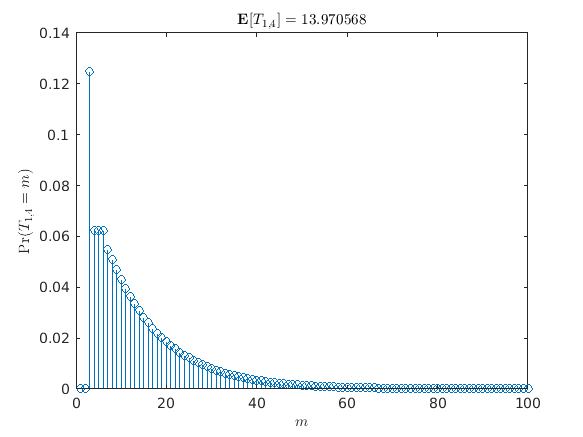


%% 2.1.a
% Write a computer program (e.g., in Python, Matlab, ...) to compute 
% $ \Pr(T_{1,4} = m) $ for $ m = 1, 2, \ldots, 100 $ and use this to 
% estimate expected number of tosses $ \mathbb{E}[T_{1,4}] $. 

P = [0.5, 0.5, 0, 0; 0.5, 0, 0.5, 0; 0.5, 0, 0 ,0.5; 0, 0, 0, 1];
% Compute Phi probabilities and expectation of hitting time
[Phi_list, ET] = compute_Phi_ET(P, 100);

m = (1:100);% ### steps to be plotted
Pr = (1:100);% ### \Pr(T_{1,4} = m) for all m
for i = 2:101
Pr(i-1) = Phi_list(1,4,i) - Phi_list(1,4,i-1);  %get Pr(T_{1,4} = m) from Phi_list
end 
E = ET(1,4);% ### \mathbb{E}[T_{1,4}]
figure()
stem(m, Pr)
xlabel('$ m $', 'Interpreter', 'latex')
ylabel('$ \Pr(T_{1,4}=m) $', 'Interpreter', 'latex')
title(sprintf('$ \\mathbf{E}[T_{1,4}] = %f $', E), 'Interpreter', 'latex')

- Write a computer program that generates 500 realizations from this Markov chain and uses them to plots a histogram of 𝑇1,4.

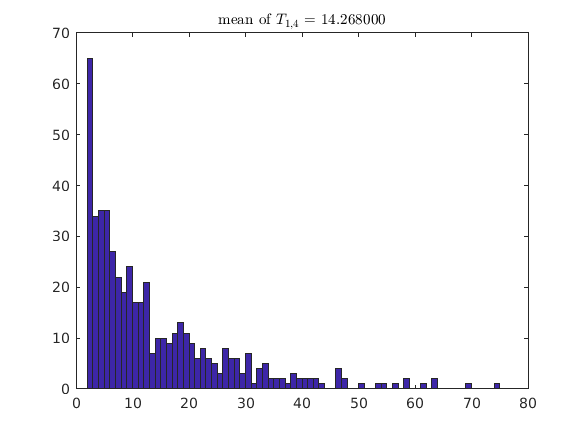


% 2.1.b
% Write a computer program that generates 500 realizations from this Markov
% chain and uses them to plots a histogram of $ T_{1,4} $.

T = simulate_hitting_time(P, [1, 4], 500);
figure()
hist(T, (0:max(T)-1) + 0.5);
title(sprintf('mean of $ T_{1,4} = $ %f', mean(T)), 'Interpreter', 'latex')

**Exercise 2.2**

Consider the miniature chutes and ladders game shown in Figure 1. Assume a player starts on the space labeled 1 and plays by rolling a fair four-sided die and then moves that number of spaces. If a player lands on the bottom of a ladder, then they automatically climb to the top. If a player lands at the top of a slide, then they automatically slide to the bottom. This process can be modeled by a Markov chain with 𝑛=16 states where each state is associated with a square where players can start their turn (e.g., players never start at the bottom of a ladder or the top of a slide). To finish the game, players must land exactly on space 20 (moves beyond this are not taken).

- Compute the transition probability matrix 𝑃 of the implied Markov chain.

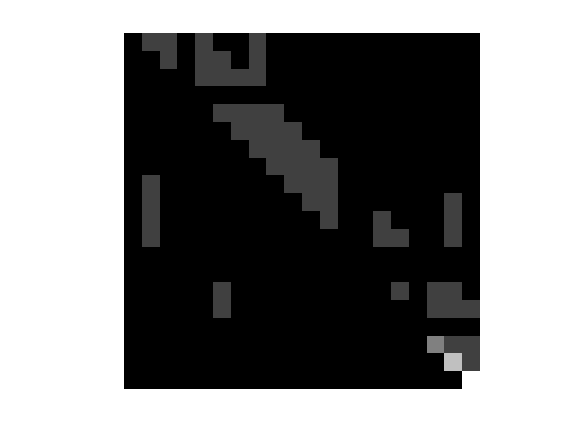

%% 2.2.a
% Compute the transition probability matrix $ P $ of the implied Markov
% chain.
%n = 20;% ### number of states
%dice = [0.25 0.25 0.25 0.25];% ### probability distribution of dice
%chutes = [17, 6; 13 12]% ### (sorce, destination) pairs of chutes
%ladders = [4, 8; 14, 9]% ### (sorce, destination) pairs of ladders
P = [0.   0.25 0.25 0.   0.25 0.   0.   0.25 0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.25 0.   0.25 0.25 0.   0.25 0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.25 0.25 0.25 0.25 0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.25 0.25 0.25 0.25 0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.   0.25 0.25 0.25 0.25 0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ; 
0.   0.   0.   0.   0.   0.   0.   0.25 0.25 0.25 0.25 0.   0.   0. 0.   0.   0.   0.   0.   0. ;  
0.   0.   0.   0.   0.   0.   0.   0.   0.25 0.25 0.25 0.25 0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.25 0.   0.   0.   0.   0.   0.   0.   0.25 0.25 0.25 0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.25 0.   0.   0.   0.   0.   0.   0.   0.   0.25 0.25 0.   0. 0.   0.   0.   0.   0.25 0. ;
0.   0.25 0.   0.   0.   0.   0.   0.   0.   0.   0.   0.25 0.   0. 0.25 0.   0.   0.   0.25 0. ;
0.   0.25 0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.25 0.25 0.   0.   0.25 0. ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.25 0.   0.   0.   0.   0.   0.   0.   0. 0.   0.25 0.   0.25 0.25 0. ;
0.   0.   0.   0.   0.   0.25 0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.25 0.25 0.25 ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   0. ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.5  0.25 0.25 ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.75 0.25 ;
0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0.   0. 0.   0.   0.   0.   0.   1. ];      
%P = construct_P_matrix(n, dice, chutes, ladders); 
%This function is also implemented, see details later;
figure()
imshow(P, 'InitialMagnification', 'fit');

- For this Markov chain, write a computer program (e.g., in Python) to compute the cumulative distribution of the number turns a player takes to finish (i.e., the probability Pr(𝑇1,20≤𝑚) where 𝑇1,20 is the hitting time from state 1 to state 20).

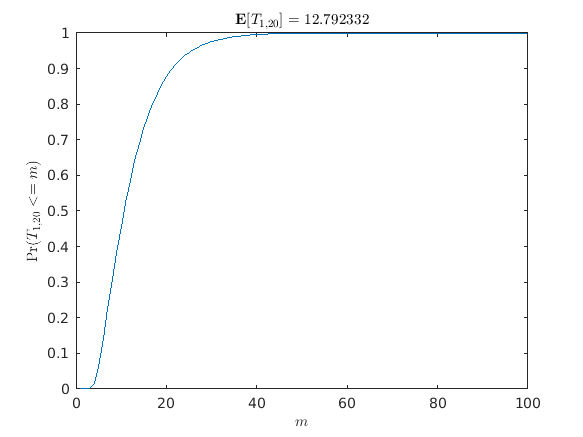

%% 2.2.b
% For this Markov chain, write a computer program (e.g., in Python, Matlab,
% ...) to compute the cumulative distribution of the number turns a player 
% takes to finish (i.e., the probability $ \Pr(T_{1, 20} \le m) $ where 
% $ T_{1, 20} $ is the hitting time from state 1 to state 20).

[Phi_list, ET] = compute_Phi_ET(P, 100);

m = 1:100;% ### steps to be plotted
Pr = 1:100;% ### \Pr(T_{1,20} <= m) for all m
for i = 2:101
Pr(i-1) = Phi_list(1,20,i);
end 
E = ET(1,20);% ### \mathbb{E}[T_{1,20}]

figure()
plot(m, Pr)
xlabel('$ m $', 'Interpreter', 'latex')
ylabel('$ \Pr(T_{1,20} <= m) $', 'Interpreter', 'latex')
title(sprintf('$ \\mathbf{E}[T_{1,20}] = %f $', E), 'Interpreter', 'latex')

- Write a computer program that generates 500 realizations from this Markov chain and uses them to plot a histogram of 𝑇1,20.

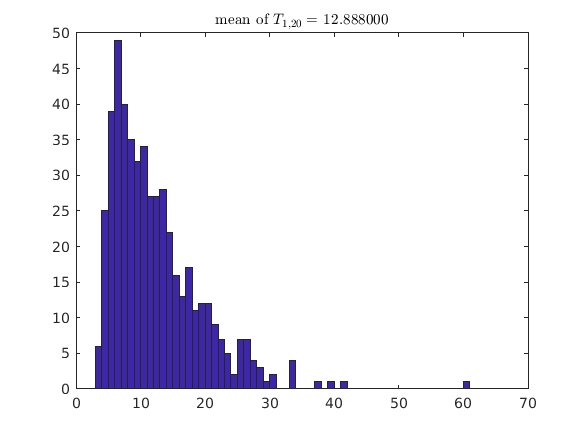

%% 2.2.c
% Write a computer program that generates 500 realizations from this Markov 
% chain and uses them to plot a histogram of $ T_{1, 20} $.
T = simulate_hitting_time(P, [1, 20], 500);
figure()
hist(T, (0:max(T)-1) + 0.5);
title(sprintf('mean of $ T_{1,20} = $ %f', mean(T)), 'Interpreter', 'latex')


%% 2.2.d
% Optional Challenge: If the first player rolls 4 and climbs the ladder to 
% square 8, then what is the probability that the second player will win.
Pr_win = 0;
% ### compute Pr_win 
fprintf('The probability that the second player will win is %f', Pr_win)

The probability that the second player will win is 0.000000

**Exercise 2.3**

In a certain city, it is said that the weather is rainy with a 90% probability if it was rainy the previous day and with a 50% probability if it not rainy the previous day. If we assume that only the previous day’s weather matters, then we can model the weather of this city by a Markov chain with 𝑛=2 states whose transitions are governed by

𝑃=$\left\lbrack \begin{array}{cc}
0\ldotp 9 & 0\ldotp 1\\
0\ldotp 5 & 0\ldotp 5
\end{array}\right\rbrack$

Under this model, what is the steady-state probability of rainy weather?

%% Exercise 2.3
% In a certain city, it is said that the weather is rainy with a 90% 
% probability if it was rainy the previous day and with a 50% probability 
% if it not rainy the previous day. If we assume that only the previous 
% day?s weather matters, then we can model the weather of this city by a 
% Markov chain with $ n = 2 $ states whose transitions are governed by
% $$
%     P = 
%     \begin{bmatrix}
%         0.9 & 0.1 \\
%         0.5 & 0.5
%     \end{bmatrix}
% $$
% Under this model, what is the steady-state probability of rainy weather?
P = [0.9, 0.1; 0.5, 0.5];
fprintf('steady-state probability of rainy weather\n')

steady-state probability of rainy weather


disp(stationary_distribution(P)')

    0.8333    0.1667



**Exercise 2.4**

Consider a game where the gameboard has 8 diﬀerent spaces arranged in a circle. During each turn, a player rolls two 4-sided dice and moves clockwise by a number of spaces equal to their sum. Deﬁne the transition matrix for this 8-state Markov chain and compute its stationary probability distribution.

%% Exercise 2.4
%% 2.4.a
% Consider a game where the gameboard has 8 different spaces arranged in a 
% circle. During each turn, a player rolls two 4-sided dice and moves 
% clockwise by a number of spaces equal to their sum. Define the transition 
% matrix for this 8-state Markov chain and compute its stationary 
% probability distribution.
P = [0.0625 0.     0.0625 0.125  0.1875 0.25   0.1875 0.125;
0.125  0.0625 0.     0.0625 0.125  0.1875 0.25   0.1875;
0.1875 0.125  0.0625 0.     0.0625 0.125  0.1875 0.25;
0.25   0.1875 0.125  0.0625 0.     0.0625 0.125  0.1875;
0.1875 0.25   0.1875 0.125  0.0625 0.     0.0625 0.125;
0.125  0.1875 0.25   0.1875 0.125  0.0625 0.     0.0625;
0.0625 0.125  0.1875 0.25   0.1875 0.125  0.0625 0.;
0.     0.0625 0.125  0.1875 0.25   0.1875 0.125  0.0625];
% ### construct the transition matrix
fprintf('steady-state probability of the first game\n')

steady-state probability of the first game


disp(stationary_distribution(P)')

    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250



Next, suppose that one space is special (e.g., state-1 of the Markov chain) and a player can only leave this space by rolling doubles (i.e., when both dice show the same value). Again, the player moves clockwise by a number of spaces equal to their sum. Deﬁne the transition matrix for this 8-state Markov chain and compute its stationary probability distribution.

%% 2.4.b
P = [0.8125  0.     0.0625 0.     0.0625 0.     0.0625 0.;
0.125  0.0625 0.     0.0625 0.125  0.1875 0.25   0.1875;
0.1875 0.125  0.0625 0.     0.0625 0.125  0.1875 0.25;
0.25   0.1875 0.125  0.0625 0.     0.0625 0.125  0.1875;
0.1875 0.25   0.1875 0.125  0.0625 0.     0.0625 0.125;
0.125  0.1875 0.25   0.1875 0.125  0.0625 0.     0.0625;
0.0625 0.125  0.1875 0.25   0.1875 0.125  0.0625 0.;
0.     0.0625 0.125  0.1875 0.25   0.1875 0.125  0.0625];
% ### construct the transition matrix
fprintf('steady-state probability of the second game\n')

steady-state probability of the second game


disp(stationary_distribution(P)')

    0.4184    0.0829    0.1018    0.0709    0.0931    0.0626    0.0959    0.0745



Following are the functions we called in our main progam.

function [Phi_list, ET] = compute_Phi_ET(P, ns)
% Arguments:
%     P -- n x n, transition matrix of the Markov chain
%     ns -- largest step to consider
% Returns:
%     Phi_list -- n x n x (ns + 1), the Phi matrix for time 0, 1, ...,ns
%     ET -- n x n, expectedd hitting time approxiamated up to step ns

    % Try to compute following quantities:
    % Phi_list(i, j, m) = phi_{i,j}^{(m)} = Pr( T_{i, j} <= m )
    % ET(i, j) = E[ T_{i, j} ] ~ \sum_{m=1}^ns m Pr( T_{i, j} = m )
[~,n] = size(P);
for i = 1:ns+1
Phi_list(:,:,i) = eye(n);%We use a list to store our data 
end
for j = 2:ns+1
Phi_list(:,:,j) = P*Phi_list(:,:,j-1);
for k = 1:n
temp=Phi_list(:,:,j);
temp(k,k) = 1;  % If it is not abosobing state we just need to change the diagnol of matrix to 1
Phi_list(:,:,j) = temp;
end
end
answer = zeros(n);
for l= 2:ns+1
answer = answer + (l-1)* (Phi_list(:,:,l) - Phi_list(:,:,l-1)); %calculating the expected hitting time
end
ET = answer;
end


function [T] = simulate_hitting_time(P, states, nr)
% Arguments:
%     P -- n x n, transition matrix of the Markov chain
%     states -- the list [start state, end state], index starts from 1
%     nr -- largest step to consider
% Returns:
%     T -- nr x 1, the hitting time of all realizations
    src = states(1);
    dst = states(2);
    if src == dst
        T = zeros(nr, 1);
    else
        T = zeros(nr, 1);
        for k=1:nr    % store our data into a list
T(k) = realization(P, src, dst); % call the realization function to implement each simulation
        end
    end
end

function [time] = realization(P, src, dst)
        state =src;
        time = 0;
        while state ~= dst
            pr = rand;
            P_row = P(state,:);   %extract every single row of transition matrix.
            seg_prob = 0;
            [~,n]=size(P);
            for i = 1:n
                seg_prob = seg_prob + P_row(i);  %segment the possiblility range
                if pr < seg_prob
                    state = i;   %if it fall in to a range we transit to the corresponding state then
                    break
                end
            end
            time = time +1;        %hitting time add 1
        end
      
        % Try to simulate following quantities:
        % T(i) = hitting time of the i-th realization
        % For sampling from a discrete distribution, see `randsrc`
end

%function [P] = construct_P_matrix(n, dice, chutes, ladders)
% Arguments:
%     n -- size of the state space
%     dice -- probability distribution of the dice outcome
%     chutes -- two columns, each row is pair of (start, end)
%     ladders -- two columns, each row is pair of (start, end)
% 
% Returns:
%     P -- n x n, transition matrix of the Markov chain
% P = zeros(n);
% for i = 1 : n-4
%     P(i+1, i+4) = 0.25;
% end
% P(n, n) = 1;
% P(n-1, n) = 0.25;
% P(n-1, n-1) = 0.75;
% P(n-2, n-1:n) = 0.25;
% P(n-2, n-2) = 0.5;
% P(n-3, n-2:n) = 0.25;
% P(n-3, n-3) = 0.5;
% P(n-4, n-4:n) = 0.25;
% [s,~] = size(ladders);%get the number of ladders
% for i = 1:s
%     P(ladders(i,1),:) = 0; %we can't start from the bottom of ladders
% end
% [P,~] = size(chutes);%get the number of chutes
% for i = 1:P
%     P(chutes(i,2),:) = 0;%we can't satrt from the top of chutes
% end
% for i = 1:n
%     for j = 1:s
%         if P(i,ladders(j,1)) ~= 0
%         P(i,ladders(j,1)) = 0; %If we land on the bottom of the ladders 
%         P(i,ladders(j,2)) = P(i,ladders(j,2)) + 0.25;%then we move to the top of ladders
%         end
%     end
% end
% for i = 1:n
%     for j = 1:q
%         if P(j,chuttes(j,2)) ~= 0
%             P(i, chutes(j,2)) = 0; %If we land on the top of chutes
%             P(i, chutes(j,1)) = P(i, chutes(j,1)) + 0.25;%then we move to the bottom of the chutes
%         end
%     end
% end
    % Construct the transition matrix of the chutes & ladders game
%end

function pi_sd = stationary_distribution(P)
% Arguments:
%     P -- n x n, transition matrix of the Markov chain
% 
% Returns:
%     pi_sd -- n x 1, stationary distribution of the Markov chain
    
    % Think pi_sd as column vector, solve linear equations:
    %     P^T pi_sd = pi_sd
    %     sum(pi_sd) = 1
v = null(transpose(P-eye(length(P))));        % we call the null function of matlab to get null space
pi_sd = v.*(ones(length(P),1)*(1./sum(v)));   % Normalization
end

